% Load the data file
load('data_5.mat');

% Extract the raw data and multiply by the amplitude unit
raw_data = data_samples.raw_data;
raw_data_v = raw_data * data_samples.amplitude_unit;

% Convert from V to µV scale
raw_data_uv = raw_data_v / 1e-6;
M = size(raw_data_uv, 1);
N = size(raw_data_uv, 2);

% Calculate the ensemble average using the mean function
S_a = mean(raw_data_uv, 1);

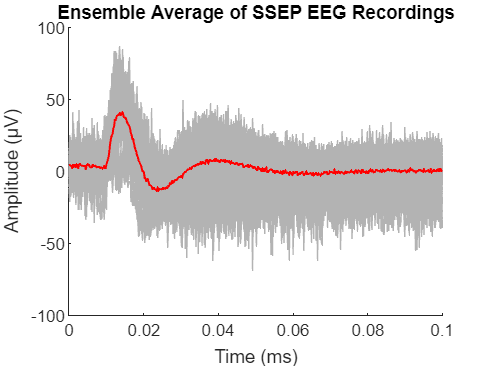

% Define the time axis
t = (0:size(raw_data, 2)-1) / data_samples.Fs;

% Plot the raw data and ensemble average in the same figure
figure;
hold on;
plot(t, raw_data_uv', 'Color', [0.7 0.7 0.7]);
xlabel('Time (ms)');
ylabel('Amplitude (µV)');
title('Raw EEG SSEP Recordings');
ylim([-100 100]);
plot(t, S_a, 'LineWidth', 1, 'Color', 'r');
xlabel('Time (ms)');
ylabel('Amplitude (µV)');
title('Ensemble Average of SSEP EEG Recordings');
ylim([-100 100]);

% Mean variance estimate
var_v = mean(mean((raw_data_uv - S_a).^2, 1), 2)

var_v = 150.2309


% Mean squared signal energy estimate
E_s = mean(S_a.^2, 2)

E_s = 91.6773


% Calculate the SNR in dB
SNR = 10 * log10(E_s / var_v)

SNR = -2.1450


% Calculate the SNR improvement due to averaging
SNR_improvement = 20 * log10(sqrt(M))

SNR_improvement = 20

chirp_model = chirp_features(data_samples);

fit_delay = chirp_model.fit_delay

fit_delay = 0.0098

t_shift = 1/chirp_model.Fs % shift on the time idx

t_shift = 2.0480e-04


peak1_loc = chirp_model.fit_first_peak_location

peak1_loc = 0.0139

peak1_amp = chirp_model.fit_first_peak_amplitude

peak1_amp = 38.8660


peak2_loc = chirp_model.fit_second_peak_location

peak2_loc = 0.0248

peak2_amp = chirp_model.fit_second_peak_amplitude

peak2_amp = 14.1568


% Find 3rd peak
slice_at = round(peak2_loc * N / 0.1)

slice_at = 121

[peak3_amp, peak3_idx] = max(chirp_model.fitted_chirp(120:N))

peak3_amp = 5.0663

peak3_idx = 66

peak3_loc = peak3_idx * 0.1 / N + peak2_loc

peak3_loc = 0.0383

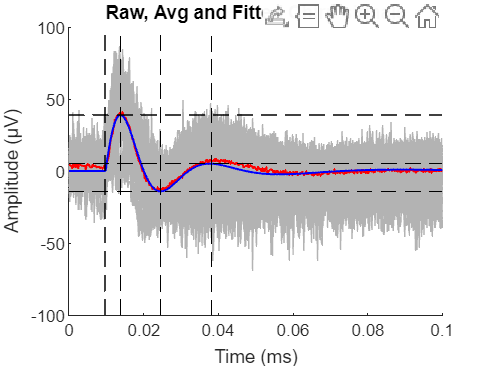

% Plot the raw data, ensemble average and fitted chirp
figure;
hold on;
plot(t, raw_data_uv', 'Color', [0.7 0.7 0.7]);
plot(t, S_a, 'LineWidth', 1, 'Color', 'r');
plot(t, chirp_model.fitted_chirp, 'LineWidth', 1, 'Color', 'b');

line([fit_delay-t_shift fit_delay-t_shift], [-100 100], 'LineStyle', '--', 'Color', 'k');
line([peak1_loc-t_shift peak1_loc-t_shift], [-100 100], 'LineStyle', '--', 'Color', 'k');
line([peak2_loc-t_shift peak2_loc-t_shift], [-100 100], 'LineStyle', '--', 'Color', 'k');
line([peak3_loc-t_shift peak3_loc-t_shift], [-100 100], 'LineStyle', '--', 'Color', 'k');

line([0 0.1], [peak1_amp peak1_amp], 'LineStyle', '--', 'Color', 'k');
line([0 0.1], [-peak2_amp -peak2_amp], 'LineStyle', '--', 'Color', 'k');
line([0 0.1], [peak3_amp peak3_amp], 'LineStyle', '--', 'Color', 'k');

xlabel('Time (ms)');
ylabel('Amplitude (µV)');
title('Raw, Avg and Fitted Chirp signals');
ylim([-100 100]);